Example 2: Inverse Laplace using Partial Fraction Decomposition

First check if there is any pole-zero cancellation

clear
syms s t

disp("      Original function in laplace domain:")

      Original function in laplace domain:


F(s)=(s^2+2*s-3)/((s - 1)*(s + 1)^2*(s^2 + 1)) % given equation

$$F(s) = \frac{s^{2}+2\,s-3}{\left(s^{2}+1\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

disp("      Compare these to see pole-zero cancellation:")

      Compare these to see pole-zero cancellation:


numerator = factor(s^2+2*s-3) % paste the numerator

$$numerator = \left(\begin{array}{cc} s+3 & s-1 \end{array}\right)$$

denominator = factor((s - 1)*(s + 1)^2*(s^2 + 1)) % paste denominator

$$denominator = \left(\begin{array}{cccc} s^{2}+1 & s-1 & s+1 & s+1 \end{array}\right)$$

disp("      Simplified F(s):")

      Simplified F(s):


simplified_F = simplify(F(s))

$$simplified\_F = \frac{s+3}{\left(s^{2}+1\right)\,{\left(s+1\right)}^{2}}$$

*If numerator and denominator share terms, there will be a coefficient of 0 (This is missing the /(s+1) term because of pole-zero cancellation)*

disp("      Partial fraction decomposition: ")

      Partial fraction decomposition: 


partial_fract = partfrac(F(s))

$$partial\_fract = \frac{3}{2\,\left(s+1\right)}-\frac{\frac{3\,s}{2}-\frac{1}{2}}{s^{2}+1}+\frac{1}{{\left(s+1\right)}^{2}}$$

disp("Inverse laplace:")

Inverse laplace:


inverse_laplace = ilaplace(F(s));
ilaplace_simple = simplify(inverse_laplace, 'Steps', 100)

$$ilaplace\_simple = \frac{3\,{\mathrm{e}}^{-t}}{2}-\frac{3\,\cos\left(t\right)}{2}+\frac{\sin\left(t\right)}{2}+t\,{\mathrm{e}}^{-t}$$

Compute ilaplace for individual terms:

terms = children(partial_fract)

terms = 1×3 cell array
    {[-((3*s)/2 - 1/2)/(s^2 + 1)]}    {[3/(2*(s + 1))]}    {[1/(s + 1)^2]}


term1 = ilaplace(sym(terms(1)))

$$term1 = \frac{\sin\left(t\right)}{2}-\frac{3\,\cos\left(t\right)}{2}$$

term2 = ilaplace(sym(terms(2)))

$$term2 = \frac{3\,{\mathrm{e}}^{-t}}{2}$$

term3 = ilaplace(sym(terms(3)))

$$term3 = t\,{\mathrm{e}}^{-t}$$

CHECK MY ANSWER GRAPHICALLY:

my_ans = sin(t)/2-3*cos(t)/2+3*exp(-t)/2+t*exp(-t) % write my calculated answer

$$my\_ans = \frac{3\,{\mathrm{e}}^{-t}}{2}-\frac{3\,\cos\left(t\right)}{2}+\frac{\sin\left(t\right)}{2}+t\,{\mathrm{e}}^{-t}$$

check_1 = F(s)-(laplace(my_ans))

$$check\_1 = \frac{3\,s}{2\,\left(s^{2}+1\right)}-\frac{1}{{\left(s+1\right)}^{2}}-\frac{3}{2\,\left(s+1\right)}-\frac{1}{2\,\left(s^{2}+1\right)}+\frac{s^{2}+2\,s-3}{\left(s^{2}+1\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

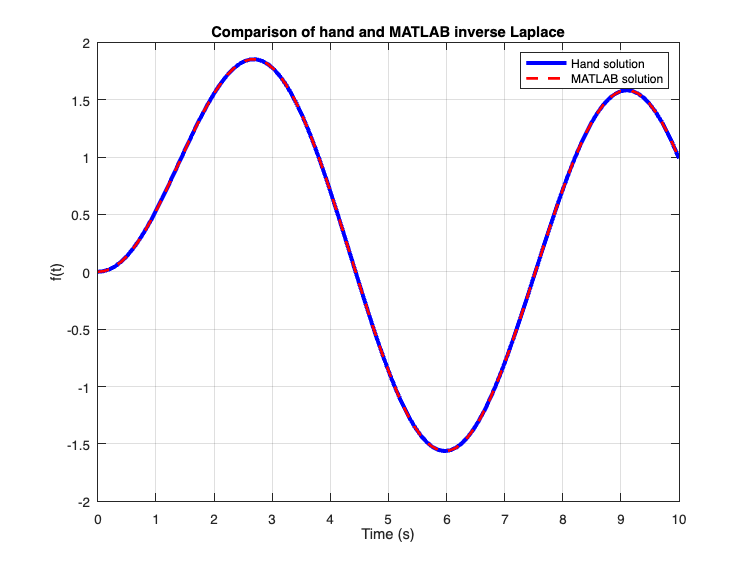


% convert symbolic to numeric functions
f_hand_fun   = matlabFunction(my_ans);
f_matlab_fun = matlabFunction(ilaplace(F(s)));

% define time variable and range
syms t
t_vals = linspace(0, 10, 100);   % time range

% evaluate both over time
y_hand   = f_hand_fun(t_vals);
y_matlab = f_matlab_fun(t_vals);


% plot both on same grid
figure
plot(t_vals, y_hand, 'b-', 'LineWidth', 3)
hold on
plot(t_vals, y_matlab, 'r--', 'LineWidth', 2)
grid on

xlabel('Time (s)')
ylabel('f(t)')
legend('Hand solution', 'MATLAB solution')
title('Comparison of hand and MATLAB inverse Laplace')